# Convergence study on transverse shear-locking

In this section it is shown how the rate of the mesh convergence study is reduced down due to transverse shear locking. The effect gets more pronounced the more slender the beam is.

Go to [THIS](matlab:open('./main_Chapter4_TransverseShearLocking_TimoshenkoBeam.mlx')) Section in the main driver script *Transverse-Shear Locking in Timoshenko beam elements - Cantilever Beam Subject to Vertical Distributed Load*

Go to [PREVIOUS](matlab:open('./main_Chapter41_TimoshenkoBeamLocking_ShearForces.mlx')) Section *Transverse-shear locking due incompatible discretization spaces*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

vars = ["mshL1" "mshL2" "X0" "XL" "NL1" "NL2" "propStr" "numEl"];
str = "This mlx-file should be run from parent mlx-file " + ...
    "main_Chapter3_Locking_TimoshenkoBeam.mlx";
for ii = 1:length(vars)
    if ~exist(vars(ii), 'var') 
        error(strcat("Variable ", vars(ii), " is not defined. ", str));
    end
end

## Initialize auxiliary arrays

wAnalytical = double(wEx(XL));
tipDeflection = zeros(numEl, 5);
numElmnts = zeros(numEl, 1);
tipDeflectionAnalytical = repmat(wAnalytical, numEl, 1);

## Loop over all the refinement levels

for ii = 1:numEl

### **One-dimensional linear mesh**

    numElmnts(ii, 1) = ii;
    mshL1Ref = generateLinearMeshOnLine(X0, XL, numElmnts(ii, 1));
    numNodesL1Ref = numel(mshL1Ref.nodes(:, 1));

### One-dimensional quadratic mesh

    mshL2Ref = generateQuadraticMeshOnLine(mshL1Ref);
    numNodesL2Ref = numel(mshL2Ref.nodes(:, 1));

### Dirichlet boundary conditions for the **one-dimensional linear mesh**

    numDOFsL1ref = 2*numNodesL1Ref;
    freeDOFsL1ref = 1:numDOFsL1ref;
    homDOFsL1ref = 1:2;
    [~, idxL1ref] = ismember(homDOFsL1ref, freeDOFsL1ref);
    freeDOFsL1ref(idxL1ref) = [];

### Dirichlet boundary conditions for the one-dimensional quadratic mesh

    numDOFsL2ref = 2*numNodesL2Ref;
    freeDOFsL2ref = 1:numDOFsL2ref;
    homDOFsL2ref = 1:2;
    [~, idxL2ref] = ismember(homDOFsL2ref, freeDOFsL2ref);
    freeDOFsL2ref(idxL2ref) = [];

### Master stiffness matrix and load vector for the one-dimensional linear mesh using full-integration

    computeStiffMatrixandForceVector = 'undefined';
    computeBasisFunctionsAndDerivs = ...
        @computeLinearBasisFunctionsAndFirstDerivatives;
    dummyInp = 'undefined';
    [KL1ref, FbodyL1ref] = ...
        computeMasterStiffMatrixandForceVectorTimoshenkoBeamPageWise ...
        (mshL1Ref, computeStiffMatrixandForceVector, ...
        computeBasisFunctionsAndDerivs, dummyInp, propStr);
    FL1boundaryref = zeros(2*numNodesL1Ref, 1);
    FL1boundaryref(end - 1, 1) = propStr.Q;
    FL1boundaryref(end, 1) = propStr.M;
    FL1ref = FbodyL1ref + FL1boundaryref;

### Master stiffness matrix and load vector for the one-dimensional linear mesh using selective-reduced integration

    computeStiffMatrixandForceVectorRI = 'undefined';
    computeBasisFunctionsAndDerivs = ...
        @computeLinearBasisFunctionsAndFirstDerivatives;
    dummyInp = 'undefined';
    [KL1RIref, FbodyL1RIref] = ...
        computeMasterStiffMatrixandForceVectorTimoshenkoBeamRIPageWise ...
        (mshL1Ref, computeStiffMatrixandForceVectorRI, ...
        computeBasisFunctionsAndDerivs, dummyInp, propStr);
    FL1boundaryRIref = zeros(2*numNodesL1Ref, 1);
    FL1boundaryRIref(end - 1, 1) = propStr.Q;
    FL1boundaryRIref(end, 1) = propStr.M;
    FL1RIRef = FbodyL1RIref + FL1boundaryRIref;

### Master stiffness matrix and load vector for the one-dimensional quadratic mesh using full-integration

    computeStiffMatrixandForceVector = 'undefined';
    computeBasisFunctionsAndDerivs = ...
        @computeQuadraticBasisFunctionsAndFirstDerivatives;
    dummyInp = 'undefined';
    [KL2Ref, FBodyL2Ref] = ...
        computeMasterStiffMatrixandForceVectorTimoshenkoBeamPageWise ...
        (mshL2Ref, computeStiffMatrixandForceVector, ...
        computeBasisFunctionsAndDerivs, dummyInp, propStr);
    FBoundaryL2Ref = zeros(2*numNodesL2Ref, 1);
    FBoundaryL2Ref(2*numNodesL1Ref - 1, 1) = propStr.Q;
    FBoundaryL2Ref(2*numNodesL1Ref, 1) = propStr.M;
    FL2Ref = FBodyL2Ref + FBoundaryL2Ref;

### Master stiffness matrix and load vector for the one-dimensional quadratric mesh using selective-reduced integration

    computeStiffMatrixandForceVectorRI = 'undefined';
    computeBasisFunctionsAndDerivs = ...
        @computeQuadraticBasisFunctionsAndFirstDerivatives;
    dummyInp = 'undefined';
    [KL2RIRef, FBodyL2RIRef] = ...
        computeMasterStiffMatrixandForceVectorTimoshenkoBeamRIPageWise ...
        (mshL2Ref, computeStiffMatrixandForceVectorRI, ...
        computeBasisFunctionsAndDerivs, dummyInp, propStr);
    FBoundaryL2RIRef = zeros(2*numNodesL2Ref, 1);
    FBoundaryL2RIRef(2*numNodesL1Ref - 1, 1) = propStr.Q;
    FBoundaryL2RIRef(2*numNodesL1Ref, 1) = propStr.M;
    FL2RIRef = FBodyL2RIRef + FBoundaryL2RIRef;

### Master stiffness matrix and load vector for the one-dimensional linear mesh corresponding to the Euler-Bernoulli formulation using the Hermitian basis functions

    computeStiffMatrixandForceVectorEBT = ...
        @computeElementStiffMatrixandForceVectorEulerBernoulliBeam;
    [KEBRef, FBodyEBRef] = ...
        computeMasterStiffMatrixandForceVectorEulerBernoulliBeam ...
        (mshL1Ref, computeStiffMatrixandForceVectorEBT, propStrEB);
    FBoundaryEBRef = zeros(2*numNodesL1Ref, 1);
    FBoundaryEBRef(end - 1, 1) = propStr.Q;
    FBoundaryEBRef(end, 1) = - propStr.M;
    FEBRef = FBodyEBRef + FBoundaryEBRef;

### Initialization of the solution vectors for the one-dimensional linear and quadratic meshes

    uL1Ref = zeros(numDOFsL1ref, 3);
    uL2Ref = zeros(numDOFsL2ref, 2);

### Solve the linear equation system corresponding to the one-dimensional linear mesh using full-integration

    uL1Ref(freeDOFsL1ref, 1) = ...
        KL1ref(freeDOFsL1ref, freeDOFsL1ref)\FL1ref(freeDOFsL1ref);
    tipDeflection(ii, 1) = uL1Ref(end - 1, 1);

### Solution of the linear equation system corresponding to the one-dimensional linear mesh using selective-reduced integration

    uL1Ref(freeDOFsL1ref, 2) = ...
        KL1RIref(freeDOFsL1ref, freeDOFsL1ref)\FL1RIRef(freeDOFsL1ref);
    tipDeflection(ii, 2) = uL1Ref(end - 1, 2);

### Solution of the linear equation system corresponding to the one-dimensional quadratic mesh using full-integration

    uL2Ref(freeDOFsL2ref, 1) = ...
        KL2Ref(freeDOFsL2ref, freeDOFsL2ref)\FL2Ref(freeDOFsL2ref);
    [~, idxRef] = sort(mshL2Ref.nodes);
    wL2Ref = uL2Ref(1:2:end, 1);
    tipDeflection(ii, 3) = wL2Ref(idxRef(end), 1);

### Solution of the linear equation system corresponding to the one-dimensional quadratic mesh using selective-reduced integration

    uL2Ref(freeDOFsL2ref, 2) = ...
        KL2RIRef(freeDOFsL2ref, freeDOFsL2ref)\FL2RIRef(freeDOFsL2ref);
    [~, idxRIRef] = sort(mshL2Ref.nodes);
    wL2RIRef = uL2Ref(1:2:end, 2);
    tipDeflection(ii, 4) = wL2RIRef(idxRIRef(end), 1);

### Solution of the linear equation system corresponding to the Euler-Bernoulli beam theory on the one-dimensional linear mesh using the Hermitian basis functions

    uL1Ref(freeDOFsL1ref, 3) = ...
        KEBRef(freeDOFsL1ref, freeDOFsL1ref)\FEBRef(freeDOFsL1ref);
    tipDeflection(ii, 5) = uL1Ref(end - 1, 3);

end

## Plot the convergence graph

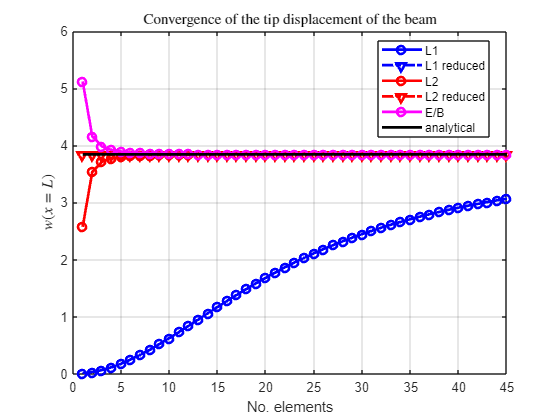

plot(numElmnts, abs(tipDeflection(:, 1)), "-bo", LineWidth=2)
hold on;
plot(numElmnts, abs(tipDeflection(:, 2)), "-.bv", LineWidth=2)
plot(numElmnts, abs(tipDeflection(:, 3)), "-ro", LineWidth=2)
plot(numElmnts, abs(tipDeflection(:, 4)), "-.rv", LineWidth=2)
plot(numElmnts, abs(tipDeflection(:, 5)), "-mo", LineWidth=2)
plot(numElmnts, abs(tipDeflectionAnalytical), "-k", LineWidth=2)
hold off;
grid on;
legend("L1", "L1 reduced", "L2", "L2 reduced", "E/B", "analytical", ...
    Location="best")
xlabel("No. elements")
ylabel("$w (x = L)$", "Interpreter","latex")
title("Convergence of the tip displacement of the beam", ...
    "Interpreter", "latex")

  **Try**

Change the value of the thickness by means of the provided slider in this code section. Change its value to the extrems and the script is going to be automatically executed.

 **Reflect**

When changing the value of the thickness to the minimum possible through the slider:

- What do you observe regarding the distribution of the transverse-shear force field in this figure?

- Which solution is off judging from the convergence graph and why?

When changing the value of the thickness to the maximum possible through the slider:

- Which solution is off in regard to the distribution of the transverse-shear force field in this figure?

- What can you tell about the convergence rates in the convergence graph of the different elements? Is this to be expected?

- What can you tell about the convergence of the Euler-Bernoulli formulation in the convergence graph? Elaborate on your answer